
Butterworth Filter Analysis:


Passband frequency: 1611.6 Hz


Number of multiplies: 17.0


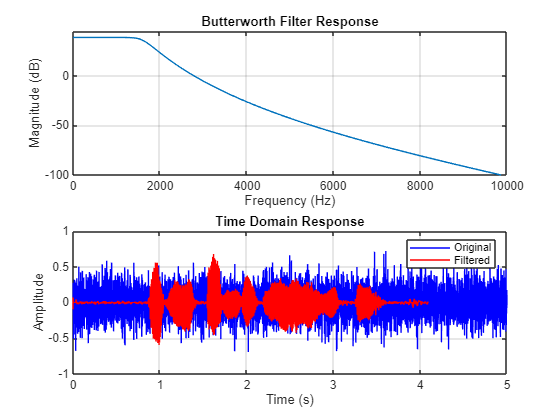


Chebyshev1 Filter Analysis:


Passband frequency: 1845.9 Hz


Number of multiplies: 17.0


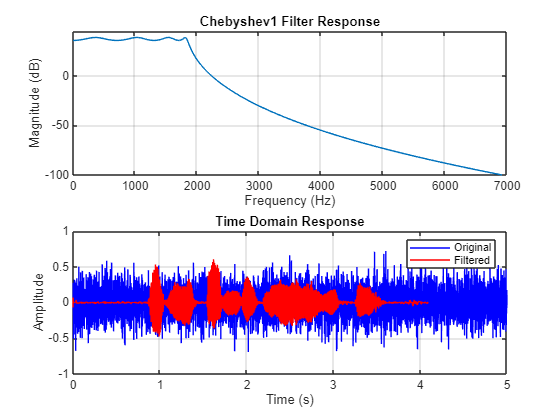


Chebyshev2 Filter Analysis:


Passband frequency: 1845.9 Hz


Number of multiplies: 17.0


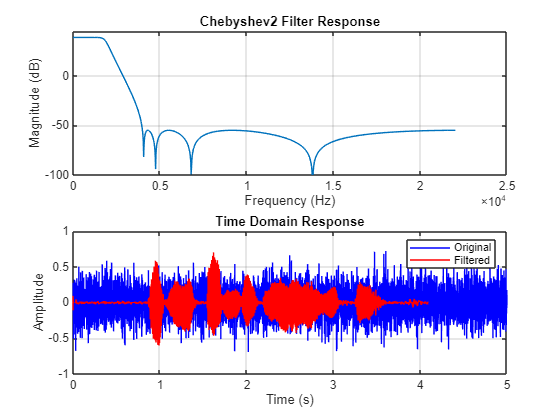

% SPDX-License-Identifier: GPL-3.0-or-later

% ECE310 Digital Signal Processing - Problem Set 1
% This script evaluates different filter designs for their frequency and
% time-domain responses. It also applies filtering and downsampling
% operations, followed by an analysis of computational requirements.

% Copyright (C) 2024 Aidan Cusa <aidancusa@gmail.com>, Kristof Jablonowski,
% Noam Schuck

% Load data and set common parameters
close all;  % Close all existing figure windows
clc;        % Clear the command window
load projIB.mat  % Load input data (e.g., 'noisy' signal)

% Global parameters
fs = 44100;          % Sampling frequency in Hz
fs_stop = 4000;      % Stopband frequency in Hz
rp = 3;              % Passband ripple in dB (difference between max and min allowed gain in passband)
rs = 93.5;           % Stopband attenuation in dB
gain = 10^(38.5/20); % Convert gain from dB to linear scale
nyq = fs / 2;        % Nyquist frequency (half the sampling rate)

% List of filter types to analyze
filter_types = {'Butterworth', 'Chebyshev1', 'Chebyshev2', 'Elliptic', ...
                'Parks-McClellan', 'Kaiser'};

% Loop through each filter type and analyze
for i = 1:length(filter_types)
    fprintf('\n%s Filter Analysis:\n', filter_types{i});
    
    % Determine optimal passband frequency and filter coefficients
    [is_fir, fp, b, a] = find_optimal_fp(filter_types{i}, fs_stop, nyq, rp, rs, gain);
    
    % Compute the frequency response of the filter
    [h, w] = freqz(b, a, 1024);  % Frequency response at 1024 points
    
    % Plot the frequency response
    figure;
    subplot(2,1,1);
    plot(w/pi * nyq, 20*log10(abs(h)));  % Convert magnitude to dB scale
    grid on;
    title(sprintf('%s Filter Response', filter_types{i}));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    ylim([-100 45]);  % Limit y-axis to visualize attenuation

    % Apply filtering and downsampling
    if is_fir
        M = 4; % Downsampling factor
        % Apply polyphase filtering and downsample using upfirdn
        downsampled_signal = upfirdn(noisy, b, 1, M);
    else
        % Apply IIR filtering
        filtered_signal = filter(b, a, noisy);
        % Downsample by taking every 4th sample
        downsampled_signal = filtered_signal(1:4:end);
    end
    
    % Count the number of multiplications required for the filter
    mults = count_multiplies(b, a, is_fir);
    fprintf('Passband frequency: %.1f Hz\n', fp);
    fprintf('Number of multiplies: %.1f\n', mults);

    % Plot the time-domain response
    subplot(2,1,2);
    plot((1:5000)/1000, noisy(1:5000), 'b', ...                % Original signal
         (1:length(downsampled_signal)) / (fs/4), downsampled_signal, 'r');  % Filtered signal
    grid on;
    title('Time Domain Response');
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend('Original', 'Filtered');

    % Play the filtered audio (optional)
    sound(downsampled_signal, fs/4);  % Play at a reduced sampling rate
    pause(6);                         % Wait for playback to finish
    clear sound;                      % Stop sound playback
    pause(1);                         % Add a short pause before the next iteration
end


% Function to count multiplications per sample
function mult_count = count_multiplies(b, a, is_fir)
    if is_fir
        % FIR filters require fewer multiplications when polyphase is used
        M = 4;  % Downsampling factor
        mult_count = ceil((length(b) - 1) / M);
    else
        % IIR filters require multiplications for all coefficients of b and a
        % except a(1), which is assumed normalized to 1
        mult_count = length(b) + length(a) - 1;
    end
end

% Function to find the optimal passband frequency and filter coefficients
function [is_fir, opt_fp, opt_b, opt_a] = find_optimal_fp(filter_type, fs_stop, nyq, rp, rs, gain)
    fp_min = 1000;  % Minimum passband frequency to consider
    fp_max = fs_stop;  % Maximum passband frequency to consider
    opt_fp = fp_min;  % Initialize optimal passband frequency
    opt_b = [];       % Initialize FIR coefficients
    opt_a = [];       % Initialize IIR coefficients
    
    % Binary search for the optimal passband frequency
    while (fp_max - fp_min) > 1
        fp_test = (fp_min + fp_max) / 2;  % Test frequency (midpoint)
        wp_test = fp_test / nyq;          % Normalize to Nyquist frequency
        ws = fs_stop / nyq;               % Normalized stopband edge
        
        switch filter_type
            case 'Butterworth'
                % Design Butterworth filter
                [n, wn] = buttord(wp_test, ws-500/nyq, rp, 55);
                [b, a] = butter(n, wn);
                is_fir = false;
            case 'Chebyshev1'
                % Design Chebyshev Type I filter
                [n, wn] = cheb1ord(wp_test, ws, rp, rs);
                [b, a] = cheby1(n, rp, wn);
                is_fir = false;
            case 'Chebyshev2'
                % Design Chebyshev Type II filter
                [n, wn] = cheb2ord(wp_test, ws, rp, rs);
                [b, a] = cheby2(n, rs, wn);
                is_fir = false;
            case 'Elliptic'
                % Design Elliptic filter
                [n, wn] = ellipord(wp_test, ws, rp, rs);
                [b, a] = ellip(n, rp, rs, wn);
                is_fir = false;
            case 'Parks-McClellan'
                % Design Parks-McClellan FIR filter
                fp = 100;
                Dpass = 0.10099735734;  % Passband ripple
                Dstop = 2.1134890398e-05;  % Stopband ripple
                dens = 20;  % Density factor
                [n, Fo, Ao, W] = firpmord([fp, fs_stop]/(nyq), [1 0], [Dpass, Dstop]);
                b = firpm(n, Fo, Ao, W, {dens});
                opt_fp = fp;  % Update optimal frequency
                opt_a = 1;    % FIR filters have a single a coefficient
                opt_b = b * (gain + 50);  % Apply gain
                is_fir = true;
                return
            case 'Kaiser'
                % Design Kaiser window FIR filter
                fp = 100;
                Dpass = 0.17099735734;  % Passband ripple
                Dstop = 2.1134890398e-05;  % Stopband ripple
                [n, wn, beta, type] = kaiserord([fp fs_stop]/(nyq), [1 0], [Dstop Dpass]);
                b = fir1(n, wn, type, kaiser(n+1, beta));
                opt_fp = fp;  % Update optimal frequency
                opt_a = 1;    % FIR filters have a single a coefficient
                opt_b = b * gain;  % Apply gain
                is_fir = true;
                return
        end
        
        % Apply gain to filter coefficients
        b = b * gain;
        
        % Check if the filter meets the multiplication constraint
        if count_multiplies(b, a, is_fir) <= 17
            fp_min = fp_test;  % Move the lower bound up
            if fp_test > opt_fp
                % Update optimal filter parameters
                opt_fp = fp_test;
                opt_b = b;
                opt_a = a;
            end
        else
            fp_max = fp_test;  % Move the upper bound down
        end
    end
end
